# Linear Control Design II - Group Work Problem Module 11

## Description		

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector. 

  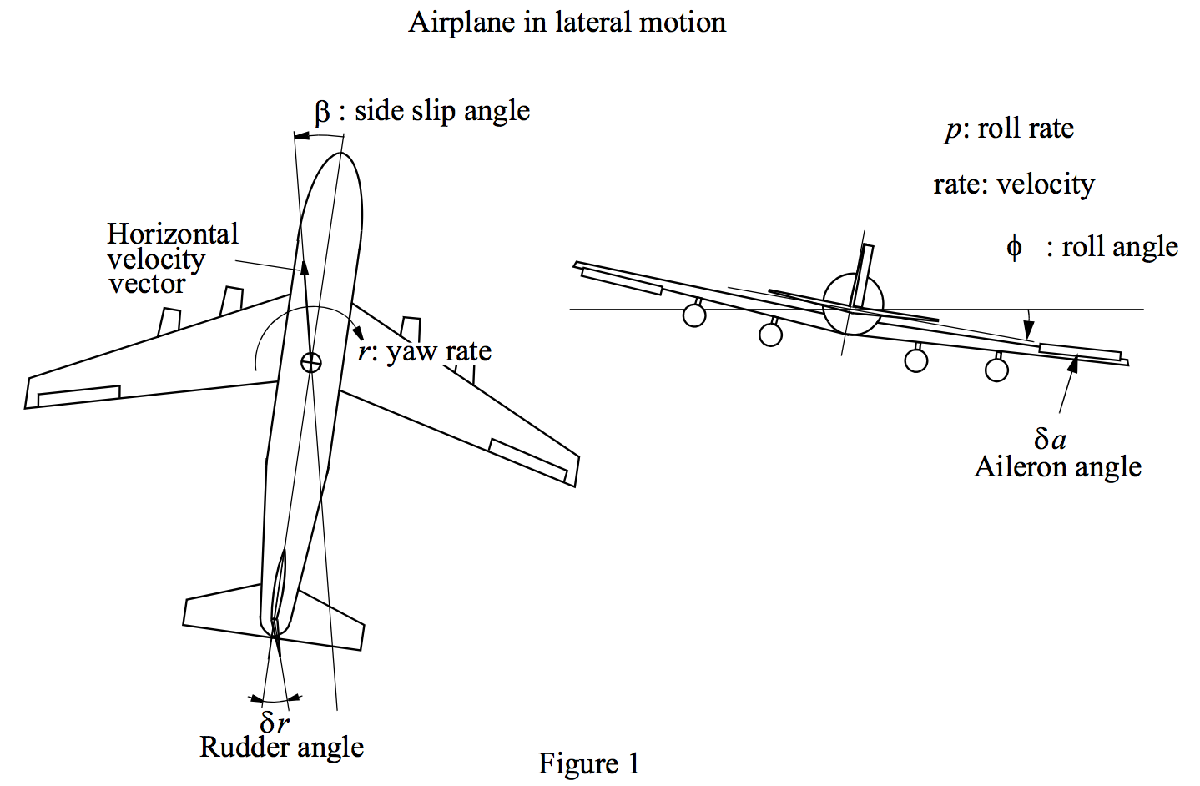

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:


$$\pmatrix{ \dot{\beta} \cr \dot{r} \cr \dot{p} \cr \dot{\varphi} } = \pmatrix{ -0.0558 &\ -0.9968 &\ 0.0802 &\ 0.0415 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr -3.0500 &\ 0.3880 &\ -0.4650 &\ 0 \cr 0 &\ 0.0805 &\ 1 &\ 0 } \pmatrix{ \beta \cr r \cr p \cr \varphi } + \pmatrix{ 0.00729 &\ 10^{-5} \cr -0.47500 &\ 0.123\cr 0.15300 &\ 1.063\cr 0 &\ 0} \pmatrix{ \delta r \cr \delta a }$$

$$y = \pmatrix{ 0 \ 1 \ 0 \ 0 \cr 0 \ 0 \ 0 \ 1 } \pmatrix{ \beta \cr r \cr p \cr \varphi}$$


where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), $\delta_r$ is the rudder deflection (rad) and $\delta_a$ is the aileron angle (rad).

format short g; clear all; close all; clc;

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

% Define state-space system:
sys_ss = ss(A,B,C,D)

sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729    1e-05
   x2   -0.475    0.123
   x3    0.153    1.063
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Problem 1  **Is the system controllable and observable?

*Use the controllability and observability matrices *$\mathbf{M_c}$* and *$\mathbf{M_o}$* (Matlab functions ctrb and obsv). How would you test whether *$\mathbf{M_c}$* has 4 linearly independent columns?*

*Also use the test with the left and the right eigenvectors (first part of PBH-test, i.e. the criteria CC3 and OC3) and the diagonal test (CC4 and OC4).*

**Solution****:**

% Your solution goes here:
Mc = ctrb(A,B);

**Controllability Theorem CC2: Rank of **$M_c$

if rank(Mc)<ndims(A)
    disp('System is not controllable')
else
    disp("System is controllable")
end

System is controllable


**Controllability Theorem CC3: PBH-test**

PBH-test:

- No $\omega_i$ exists such that $\omega_i^TB=0$

- rank$[SI-A\ B]=n$ for all s

The left eigenvectors of A is the right eigenvectors of A'

[V,E,W]=eig(A);
% OR
% [W,D]=eig(A')
disp('Left eigenvector: ');W

Left eigenvector: 


W =   -0.0883 + 0.6768i  -0.0883 - 0.6768i  -0.4723 + 0.0000i  -0.0211 + 0.0000i
   0.7264 + 0.0000i   0.7264 + 0.0000i  -0.8462 + 0.0000i   0.9739 + 0.0000i
  -0.0670 - 0.0325i  -0.0670 + 0.0325i  -0.2444 + 0.0000i   0.1913 + 0.0000i
  -0.0295 - 0.0049i  -0.0295 + 0.0049i   0.0348 + 0.0000i   0.1202 + 0.0000i


disp('transpose(W)*B');W'*B

transpose(W)*B


ans =   -0.3559 + 0.0000i   0.0181 + 0.0345i
  -0.3559 - 0.0000i   0.0181 - 0.0345i
   0.3611 + 0.0000i  -0.3639 + 0.0000i
  -0.4335 + 0.0000i   0.3231 + 0.0000i


Since no $\omega_i^TB=0$, the first part of CCS indicates that the system is controllable.

**Controllability Theorem CC4: For diagonal system with distinct eigenvalues, No zero-rows in B**

Bt = inv(V)*B

Bt =    0.6355 - 0.8972i  -0.1194 - 0.0159i
   0.6355 + 0.8972i  -0.1194 + 0.0159i
   2.1477 + 0.0000i  -2.1643 - 0.0000i
  -2.7555 - 0.0000i   2.0539 + 0.0000i


No rows in Bt is zero, so the system is controllable

**Observability Theorem OC2: Rank of**$M_o
$

Mo = obsv(A,C);
if rank(Mo)<ndims(A)
    disp('System is not observable')
else
    disp("System is observable")
end

System is observable


**Observability Theorem OC3: PBH-test**

No $v_i$ exists such that$Cv_i=0$ or rank$\left[\matrix{C \cr SI-A}\right]=n$ for all s

disp(C*V)

    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i



**Observability Theorem OC4: For diagonal system, No zero rows in C**

Ct = C*V

Ct =   -0.0780 - 0.1333i  -0.0780 + 0.1333i  -0.0118 + 0.0000i   0.0404 + 0.0000i
   0.6930 + 0.0000i   0.6930 + 0.0000i   0.8717 + 0.0000i   0.9991 + 0.0000i


**Problem 2  **Find the 4 transfer functions and determine the 4 sets of poles and zeros. 

**Solution:**

The inputs are $u=[\delta_r \ \delta_a]^T$. The outputs are $y=[r \ \varphi]^T$


$$u=\left[\matrix{\delta_r \cr \delta_a}\right] \\ 
y=\left[\matrix{r \cr \varphi}\right]$$



$$sys\_tf=\left[\matrix{\delta_r\to r \ \delta_a \to r \cr \delta_r \to \varphi \ \delta_a \to \varphi}\right]$$


% Your solution goes here:
sys_ss = ss(A,B,C,D);
sys_ss.u={'\delta_r','\delta_a'};
sys_ss.y={'r','\phi'};

% compute the transfer function matrix
sys_tf = zpk(minreal(tf(sys_ss)))

sys_tf =
 
  From input "\delta_r" to output...
          -0.475 (s+0.4981) (s^2 + 0.02379s + 0.2381)
   r:  -------------------------------------------------
       (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
                     0.11476 (s-4.44) (s+2.694)
   \phi:  -------------------------------------------------
          (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
  From input "\delta_a" to output...
           0.123 (s+0.4484) (s^2 - 0.2024s + 0.7605)
   r:  -------------------------------------------------
       (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
                   1.0729 (s^2 + 0.2159s + 0.9541)
   \phi:  -------------------------------------------------
          (s+0.5627) (s+0.007278) (s^2 + 0.06587s + 0.8972)
 
Continuous-time zero/pole/gain model.



% the poles are the same for all transform functions
disp(pole(sys_tf(1,1)))

    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i



% zeros(sys_tf(1,1))
% zeros(sys_tf(1,2))
% zeros(sys_tf(2,1))
% zeros(sys_tf(2,1))

for ii = 1:size(sys_tf,1)
    for jj = 1:size(sys_tf,1)
        disp(['Zeros from ' sys_tf.u{ii} ' to ' sys_tf.y{jj} ' : '])
        disp(zero(sys_tf(ii,jj)));
    end
end

Zeros from \delta_r to r : 


     -0.49808 +          0i
    -0.011893 +    0.48779i
    -0.011893 -    0.48779i



Zeros from \delta_r to \phi : 


      0.10121 +    0.86618i
      0.10121 -    0.86618i
     -0.44845 +          0i



Zeros from \delta_a to r : 


       4.4398
       -2.694



Zeros from \delta_a to \phi : 


     -0.10797 +    0.97082i
     -0.10797 -    0.97082i



**Problem 3  **Set up a detailed Simulink model of the airplane. Base the model on figure 2.3 in the textbook. Note: One can use the MatrixGain-block as well as the usual Gain-block, but be sure that it is set up for matrix-multiplication. 

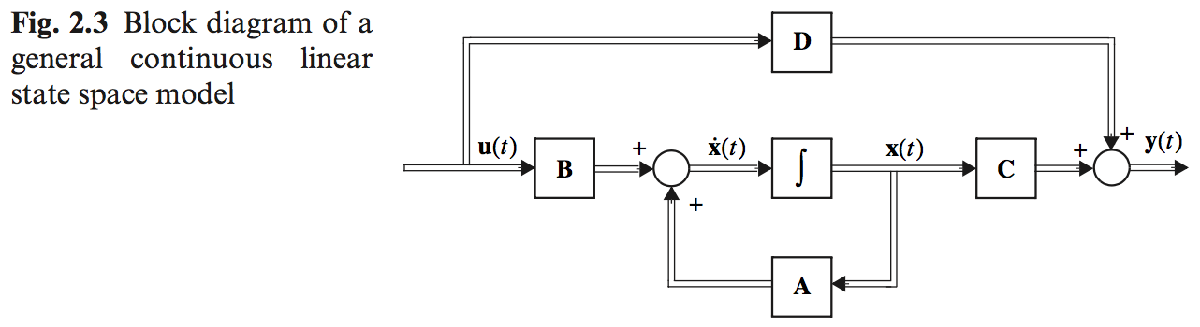

**Solution:**

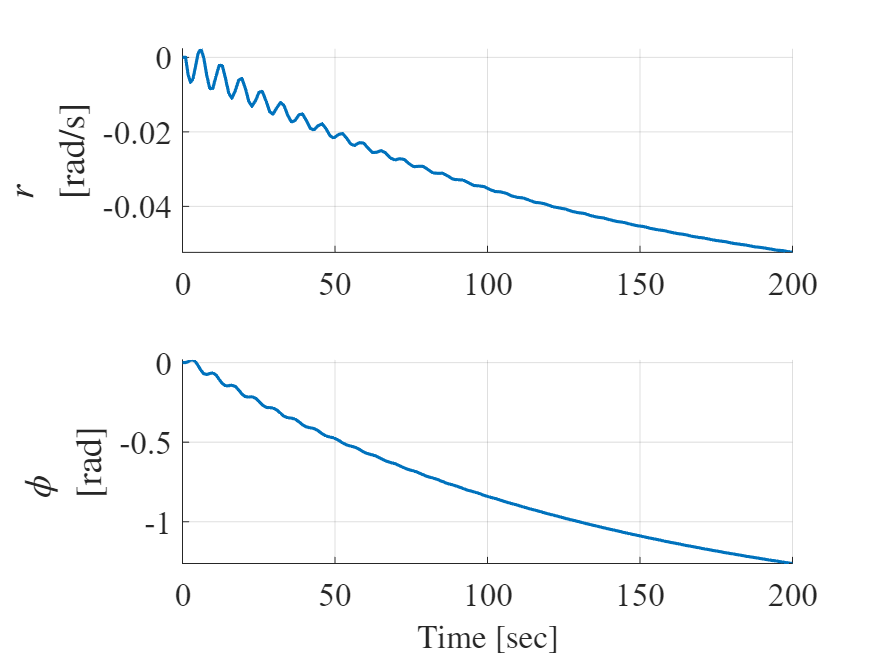

% Your solution goes here:
u = [1*pi/180;1*pi/180];
sim('My747');

figure
h1 = subplot(2,1,1);
set(h1,'FontName','times','FontSize',16)
hold on
grid on
plot(simout.time,simout.signals.values(:,1),'LineWidth',1.5);
ylabel('$$r$$ [rad/s]','Interpreter','latex');

h2 = subplot(2,1,2);
set(h2,'FontName','times','FontSize',16)
hold on
grid on
plot(simout.time,simout.signals.values(:,2),'LineWidth',1.5);
ylabel('$$\phi$$ [rad]','Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');

**Problem 4  **Find the 4 step responses (use the angle 1° for both inputs) and plot them in a 2 by 2 array using Matlab’s subplot-function. 

**Solution:**

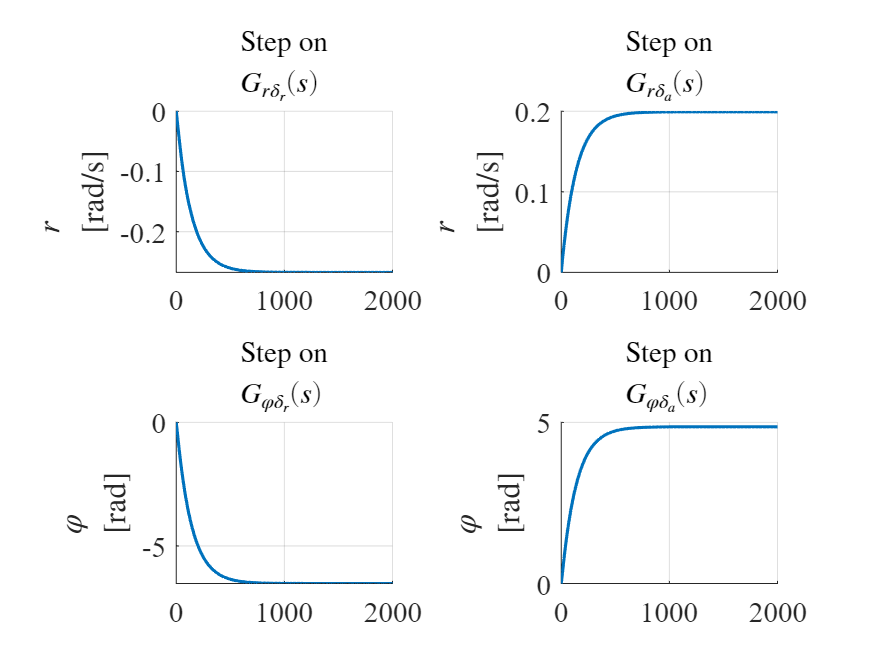

% Your solution goes here:
tfinal = 2000;

figure

h3 = subplot(2,2,1);
set(h3,'FontName','times','FontSize',14)
hold on
grid on
[y1,t1]=step(sys_tf(1,1)*pi/180,tfinal);
plot(t1,y1,'LineWidth',1.5);
title('Step on $$G_{r \delta_r}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/s]','Interpreter','latex');

h4 = subplot(2,2,2);
set(h4,'FontName','times','FontSize',14)
hold on
grid on
[y2,t2]=step(sys_tf(1,2)*pi/180,tfinal);
plot(t2,y2,'LineWidth',1.5);
title('Step on $$G_{r \delta_a}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/s]','Interpreter','latex');

h5 = subplot(2,2,3);
set(h5,'FontName','times','FontSize',14)
hold on
grid on
[y3,t3]=step(sys_tf(2,1)*pi/180,tfinal);
plot(t3,y3,'LineWidth',1.5);
title('Step on $$G_{\varphi \delta_r}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$\varphi$$ [rad]','Interpreter','latex');

h6 = subplot(2,2,4);
set(h6,'FontName','times','FontSize',14)
hold on
grid on
[y4,t4]=step(sys_tf(2,2)*pi/180,tfinal);
plot(t4,y4,'LineWidth',1.5);
title('Step on $$G_{\varphi \delta_a}(s)$$','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$\varphi$$ [rad]','Interpreter','latex');

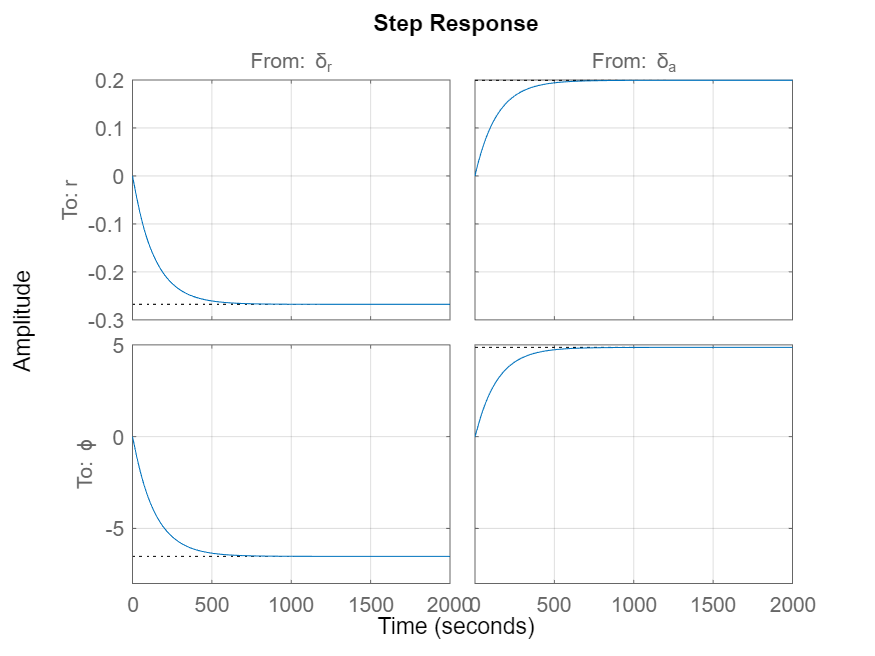

figure
step(sys_tf*pi/180,tfinal)
grid

**Problem 5**  Last, simulate the response of the linear system by using the function on figure 2 at both inputs, but one at a time.

Is it possible to change the airplane’s heading by manipulating the ailerons only? 

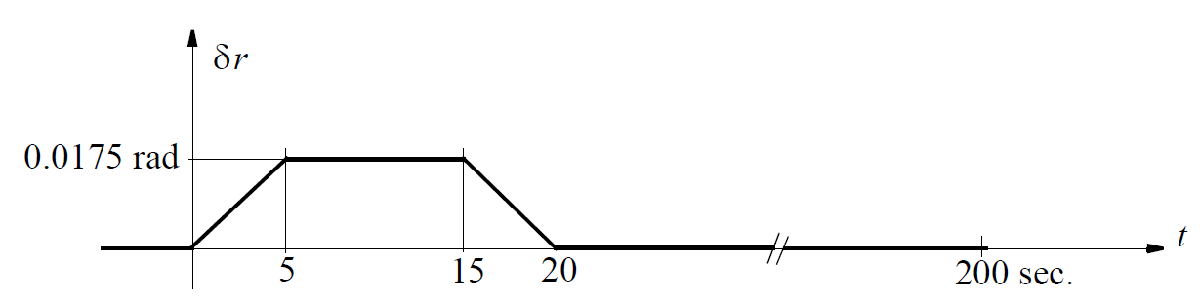	

**Solution:**

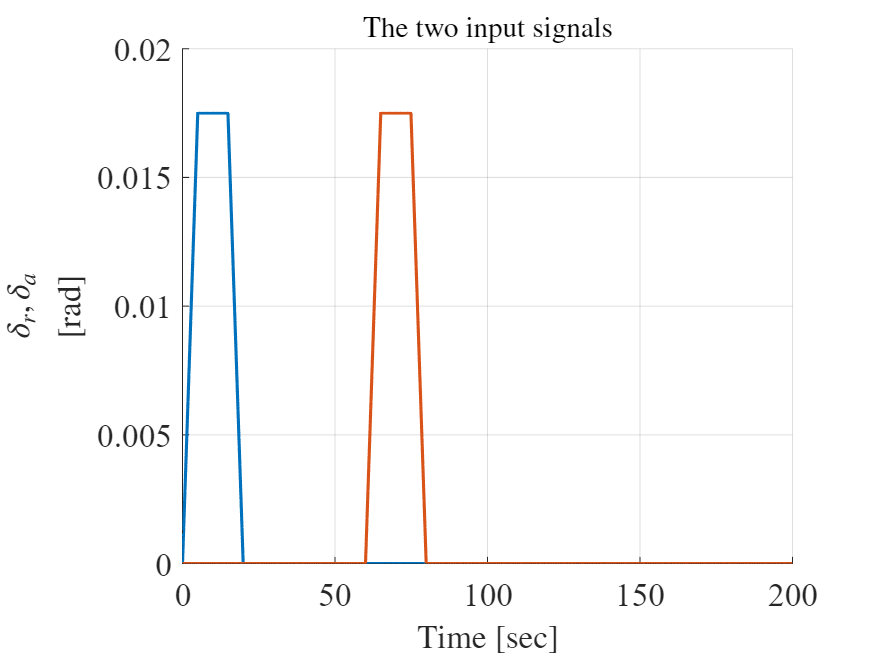

% Your solution goes here:
t = 0:0.1:199.9;
bias = 600;
ut1 = (0:50)*0.0175/50;
ut2 = ones(1,98)*0.0175;
ut3 = (0:50)*(-0.0175/50)+0.0175;
ut4 = zeros(1,1800);
ut5 = zeros(1,bias);
ut6 = zeros(1,1800-bias);
uttot1 = [ut1 ut2 ut3 ut4];
uttot2 = [ut5 ut1 ut2 ut3 ut6];
u = [uttot1;uttot2];

figure
figure, h7 = axes; set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(t,u,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');
ylabel('$$\delta_r, \, \delta_a$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
title('The two input signals','FontName','times','FontSize',14,'Interpreter','latex');

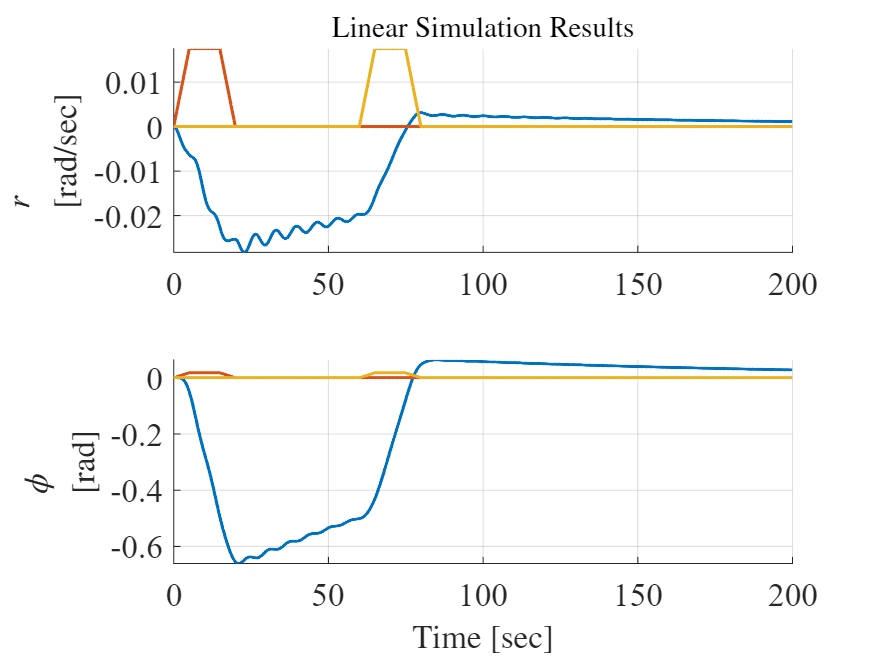

y = lsim(A,B,C,D,u,t,[0 0 0 0]');
figure, h8 = subplot(2,1,1); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,1),t,u,'LineWidth',1.5)
title('Linear Simulation Results','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',16,'Interpreter','latex');
h9 = subplot(2,1,2); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,2),t,u,'LineWidth',1.5)
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');

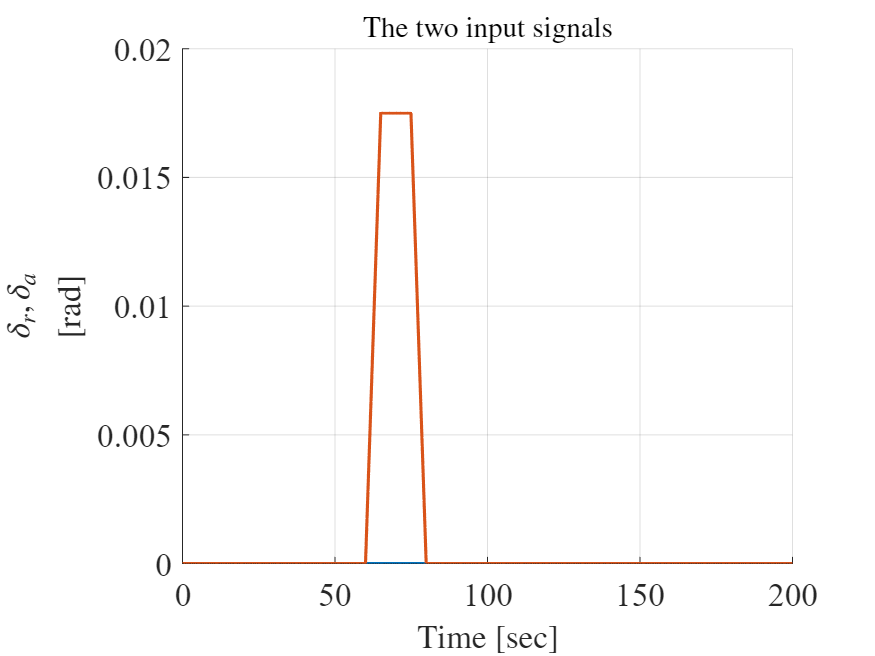

t = 0:0.1:199.9;
bias = 600;
ut1 = (0:50)*0.0175/50;
ut2 = ones(1,98)*0.0175;
ut3 = (0:50)*(-0.0175/50)+0.0175;
ut4 = zeros(1,1800);
ut5 = zeros(1,bias);
ut6 = zeros(1,1800-bias);
uttot1 = [ut1 ut2 ut3 ut4];
uttot2 = [ut5 ut1 ut2 ut3 ut6];
u = [zeros(1,2000);uttot2];

figure
figure, h7 = axes; set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(t,u,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');
ylabel('$$\delta_r, \, \delta_a$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
title('The two input signals','FontName','times','FontSize',14,'Interpreter','latex');

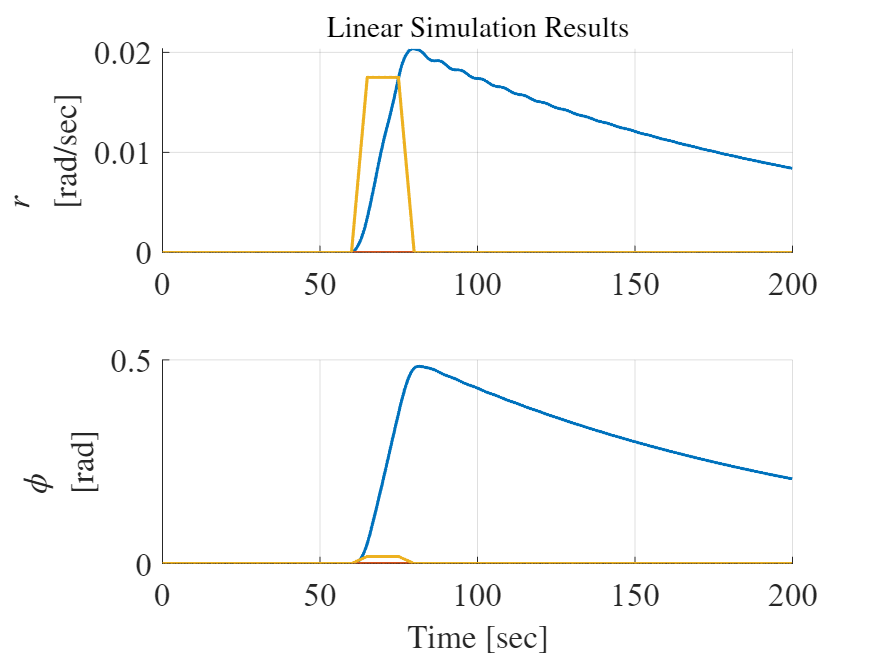

y = lsim(A,B,C,D,u,t,[0 0 0 0]');
figure, h8 = subplot(2,1,1); set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,1),t,u,'LineWidth',1.5)
title('Linear Simulation Results','FontName','times','FontSize',14,'Interpreter','latex');
ylabel('$$r$$ [rad/sec]','FontName','times','FontSize',16,'Interpreter','latex');
h9 = subplot(2,1,2); set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(t,y(:,2),t,u,'LineWidth',1.5)
ylabel('$$\phi$$ [rad]','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');

**Diagonal System**

E

E =   -0.0329 + 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0329 - 0.9467i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5627 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0073 + 0.0000i


Bt

Bt =    0.6355 - 0.8972i  -0.1194 - 0.0159i
   0.6355 + 0.8972i  -0.1194 + 0.0159i
   2.1477 + 0.0000i  -2.1643 - 0.0000i
  -2.7555 - 0.0000i   2.0539 + 0.0000i
